# **ACTIVIDAD 1**

**Se desea decimar una señal x[n] por un factor de M = 5. En el campus puede encontrar esta señal en el archivo *****'x_input.mat'*****. **

**a)**

** Realice el submuestreo directo de la señal x[n] y grafique su espectro junto al de la entrada (en el intervalo [0, 2𝜋) ). Se recomienda normalizar la amplitud de cada espectro para poder compararlos. ¿Por cuánto se escala el espectro de la señal submuestreada? ¿Podría recuperarse la señal original? **

%si se comprime en tiempo, se expande en frecuencia.
clear; close all; clc;
%Cargo la señal de entrada.
x_input = load('x_input.mat');
%Constante de decimacion
M = 5;
%Cargo en x la señal.
x = x_input.x;
%cantidad de puntos para las frecuencias a graficar.
nfft = 2*length(x);   %como minimo el largo de la señal

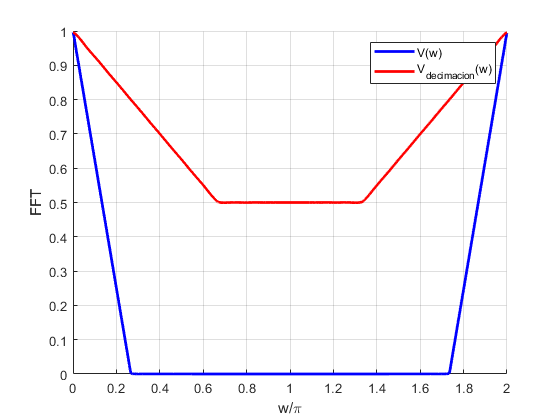


%dowsample, upsample
%Decimo: de x tomo la muestra 1 M 2M 3M ... end/ x(end) es la ultima muestra
xd = x(1:M:end);

%Calculo la DFT de x.
X = fft(x, nfft);
%Calculo de DFT de x discretisada, xd.
Xd = fft(xd, nfft);
%Creo la base de frecuencias.
w= linspace(0, 2*pi, nfft);

%Nota: si pensamos en la energia de la señal, en el dominio del espectro
%(W) el decimar es crecer en frecuencia (dado que en tiempo es decrecer)
%puesto que se tiene que cumplir la igualdad de areas (A1.W1 = A2.W2) y de
%ahi se ve como tiene que disminuir la amplitud de la señal decimada.
%Tambien se puede pensar en el tiempo, si yo tomo menos muestras en tiempo
%entonces estoy tomando menos energia de la señal original por lo que tengo
%menos energia en xd, menos amplitud en frecuencia, y todo esto en una
%factor M. POR ELLO SE REESCALA 'xd' EN 'M' PARA GRAFICAR.
figure()
    hold on
    plot(w/pi, abs(X), '-b', 'LineWidth', 2)
    plot(w/pi, abs(Xd)*M, '-r', 'LineWidth', 2)
    xlim([0 2])
    legend("V(w)", "V_{decimacion}(w)")
    xlabel("w/\pi")
    ylabel("FFT")
    grid on

    
%Ahora lo que se ve es que hay aliasing, osea el azul es el
%normal sin decimar, pero el rojo es con decimacion y se ve que la señal en
%2*pi (que era la misma que en cero)tambien crece en frecuencia en M (w*5)
%por lo que se produce aliasing y uno lo que quiere hacer es quiza cortar
%justo en la maxima frecuencia PI/5 en este caso, en general PI/M.
%POR QUE?
%Bueno si nos fijamos ws = 2.PI osea que la señal x se repite cada 2.PI
%pero cuando decimamos se tiene que cumolir Nyquist wmax < ws/2, decimando
%wmax/M < ws/2M pero quien es wmax? bueno se wmax = ws/2 (justo el limite)
%y ws = 2pi para x, entonces wmax = pi, lo cual tiene sentido viendo la
%imagen azul, mi espectro solo debe llegar hasta PI, sino hay aliasin
%entonces si decimo tendrá que llegar hasta PI/M.

**b) **

**Implemente un filtro FIR H(z) de acuerdo al esquema de la Figura con un diseño adecuado para evitar el efecto aliasing. ¿Qué frecuencia de corte elegiría? Utilice un filtro FLG óptimo (LS) con 𝛿S =𝛿p=0.01 y 𝛥𝜔=0.01𝜋. Obtenga y[n] a la salida y grafique su espectro junto al de x[n] y v[n]. Por otro lado, grafique los espectros de la señal y[n] con y sin el filtro implementado. Observe los resultados y analice la necesidad de utilizar el esquema de la Figura.**

             

deltaP = 0.01;
deltaS = deltaP;
%Para asegurarnos que no haya Aliasing ws=pi/M en la teorica, pero aca
%usamos wc = pi/M, como si fuera ideal... bueno...
Dw = 0.01*pi;
wc= pi/5;
wp= wc - Dw/2;
ws= wc + Dw/2;


**En las teoricas **$\pi/M$** es usualmente el **$w_s$** aca es la freucuencia de corte **$W_c$**.**

%Se eleigen las bandas del filtro LS
F= [0 wp ws pi]/pi;
%Amplitudes.
A= [1 1 0 0];
%Ripple.
R= [deltaP deltaS]

R =     0.0100    0.0100


N = 401;  %sale de una estimacion de kaiser.
%Para generar el filtro LS en matlab es:
ls = firls(N, F, A, 1./R) %filtro anti-aliasing

ls =     0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000


%Calculo su DFT (Transformada Discreta de Fourier).
LS = fft(ls, nfft);

%una señal pasada por el filtro es Y=H.X en el tiempo_d es y = h * x (convolucion)
y = conv(ls,x)

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000


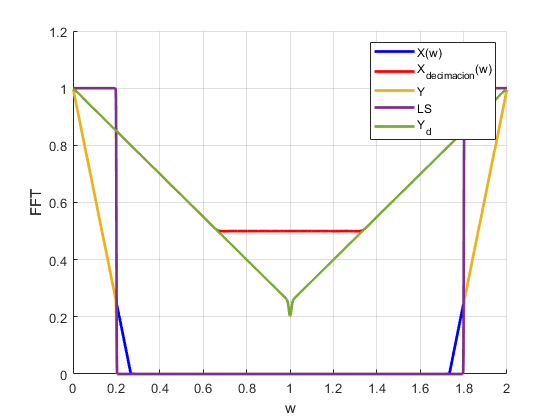

%La señal decimada cada M usar dowsample(), pero es lo mismo que:
yd = y(1:M:end);
%Calculo su DFT.
Y = fft(y, nfft);
Yd= fft(yd, nfft);

%  {, "LineWidth",1)} cambia el ancho de las lineas en el plot.
figure()
    hold on
    plot(w/pi, abs(X), '-b', "LineWidth", 2)
    plot(w/pi, abs(Xd)*M, '-r', "LineWidth", 2)
    plot(w/pi, abs(Y), "LineWidth", 2)
    plot(w/pi, abs(LS), "LineWidth", 2)
    plot(w/pi, abs(Yd)*M, "LineWidth", 2)
    
    xlim([0 2])
    legend("X(w)", "X_{decimacion}(w)", "Y", "LS", "Y_d")
    xlabel("w")
    ylabel("FFT")
    grid on

Notar que la señal X(w) es la señal sin decimar, luego X_d(w) es la decimada, claramente tiene Aliasin por lo que se propone usar un filtro Anti-Aliasing dado por LS.

Entonces primero se se filtra con LS  obteniendo $Y$y luego se decima por $M$, dado asi $Y_d$ que como se ve ya no tiene Aliasing comparado con $X_d$ (rojo).

# **Actividad 2**

**Se desea realizar la interpolación de una señal x[n] por un factor de L= 3. Utilice la misma señal de entrada del Ejercicio 1. **

**a)**

** Realice el sobremuestreo de x[n] (puede utilizar la función *****upsample(x,L)***** ) y observe su respuesta temporal mediante stem(). Grafique simultáneamente los espectros de x[n] y w[n]. ¿En cuánto se redujo el ancho de banda de la señal luego de la expansión temporal?.**

%Constante de sobremuestreo.
L=3

L = 3

%Se hace el sombremuestreo con upsample(), es agregar ceros entre muestras
w_up = upsample(x, L)

w_up =     0.0001         0         0    0.0000         0         0    0.0000         0         0    0.0000         0         0    0.0000         0         0    0.0001         0         0    0.0001         0         0    0.0001         0         0    0.0000         0         0    0.0000         0         0    0.0000         0         0    0.0000         0         0    0.0001         0         0    0.0001         0         0    0.0001         0         0    0.0001         0         0    0.0000         0


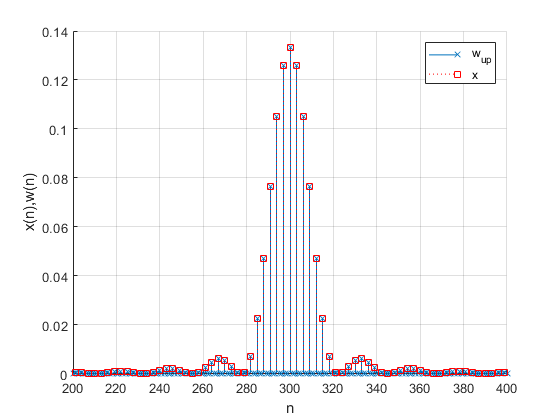


figure()
    hold on
    stem(0:length(w_up)-1, w_up, 'x')
    stem(0:L:length(x)*L-L, x, ':squarer')
    legend("w_{up}", "x")
    xlim([200 400])
    grid on
    xlabel("n")
    ylabel("x(n),w(n)")

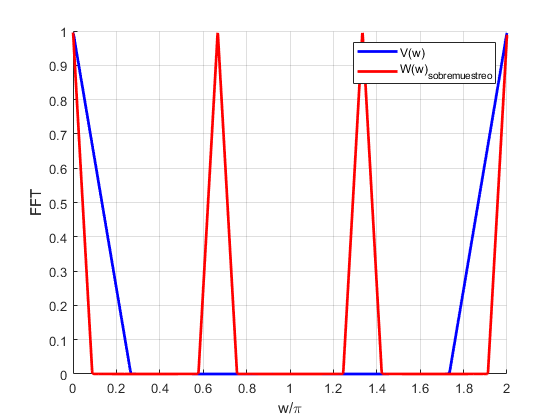

    
%el ancho de banda se debe reducir 3 veces.
%Pero hay que tener en cuenta que agregar ceros en medio no hace que que la
%energia cambie, la energia se mantiene, pero si tomaramos el espectro de
%cero a pi, bueno ahí si estaria reducion mi energia en L.

%este no es el caso por ello no hay disminucion de amplitud.
W = fft(w_up, nfft);

figure()
    hold on
    plot(w/pi, abs(X), '-b', "LineWidth", 2)
    plot(w/pi, abs(W), '-r', "LineWidth", 2)
    %plot(w/pi, abs(LS))
    %plot(w/pi, abs(Y)*M)
    xlim([0 2])
    legend("V(w)", "W(w)_{sobremuestreo}")
    xlabel("w/\pi")
    ylabel("FFT")
    grid on

    %Se redduce en pi/5.
    %aparecen muestraas de la señal sobremeuestreada.
    

La base de tiempo en la señal se agranda por lo que en frecuencia debe disminuir.

**b) **

**De acuerdo al esquema de la Figura, implemente un filtro FIR H(z), con mismos parámetros que el ejercicio anterior, pero con frecuencias adecuadas para realizar el interpolado. Obtenga y[n] y grafique su espectro junto al de x[n] y w[n]. Por otro lado, grafique con stem(), w[n] e y[n] en el tiempo y verifique el interpolado. ¿Es necesario escalar la secuencia de salida  y[n]?.    **

        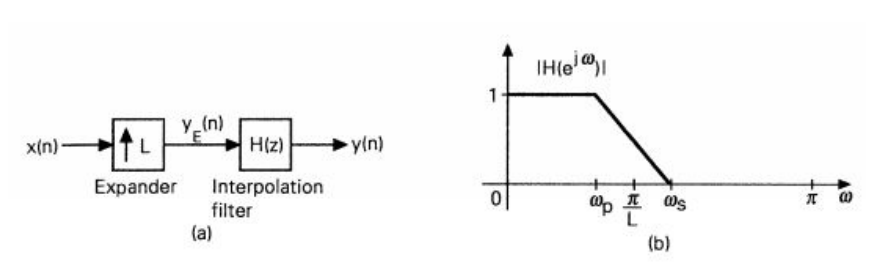

%esto se elige para evitar la supersopiscion de repeticiones dentro del rango 
% de 2*pi por que ahora wc/L hasta el 2*pi aparecen mas triangulos y 
% no queremos que se superponga aunque siempre un caso maximo va a aser pi.
wc= pi/L;

Dw = 0.01*pi;
wp= wc - Dw/2;
ws= wc + Dw/2;

%filtro de interpolacion
F= [0 wp ws pi]/pi;
A= [1 1 0 0];
R= [deltaP deltaS]

R =     0.0100    0.0100


%b = firls(nfft,f,a);

ls = firls(nfft, F, A, 1./R) %filtro anti-aliasing

ls =    -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000


%Normalizo el filtro.
ls = ls / max(ls);
LS = fft(ls, nfft); %la dft me lo reescala en L


%Respuesta en frecuencia del sobremuestreo.
W = fft(w_up, nfft);

%Señal pasada por el interpolador.
%si le aplicas el interpolador, eliminas las imágenes y te quedas solo con 
% los espectros en 0 y pi. Esto en tiempo implica que la señal perdió parte 
% de su energía (al eliminar las imágenes), por eso es que se reduce su amplitud 
% por un factor de L.

y_up = conv(w_up, ls);
%y_up = conv(L.*w_up, ls); %con esto en tiempo tenemos las mismas amplitudes.
Y_up = fft(y_up, nfft);

figure()
    hold on
    plot(w/pi, abs(X), '-b', 'LineWidth', 2)
    plot(w/pi, abs(W), '-r', 'LineWidth', 2)
    plot(w/pi, abs(LS)/L, 'LineWidth', 2)
    plot(w/pi, abs(Y_up)/L, 'LineWidth', 2)
    xlim([0 2])
    legend("V(w)", "W(w)_{sobremuestreo}", "LS", "Y_up")
    xlabel("w/\pi")
    ylabel("FFT")
    grid on
    
% figure()
%     hold on
%     plot(L*w/pi, abs(LS))
%     plot(L*w/pi, abs(Y_up))
%     xlim([0 2])
%     legend("LS", "Y_up")
%     xlabel("w")
%     ylabel("FFT")
%     grid on

figure()
    hold on
    stem(0:L:length(w_up)*L-L, w_up) %verificar
    stem(0:L:length(y_up)*L-L, y_up) 
    %stem(0:length(x)-1, x)
    legend("w_{up}", "y_{up}")
    xlim([0 5000])
    grid on
    xlabel("n")
    ylabel("w_{up}(n), y_{up}(n)")
    
%Hay que reescalar la amplitud.


#### Actividad 3

#### Tasa de muestreo fraccional

clc; clear;
x_input = load('x_input.mat');

 **Un sistema debe procesar una señal digital x[n] muestreada a 12 kHz, pero dado que el sistema posee solo un conversor D/A de 28 kHz para reconstruir la señal, se requiere implementar una etapa de remuestreo para permitir la compatibilidad con el sistema (ver Figura). **

**a) Determine los factores L y M tal que se cumpla con el requerimiento de muestreo en la señal de salida y[n]. **

%fs2/fs1 = 28/12 = 7/3.
L = 7;
M = 3;
Q = L/M;

**b) Considerando las mismas tolerancias del ejercicio 1 y 2, determine las frecuencias de corte de los filtros de interpolación y antialiasing. Implemente el filtro que considere apropiado. ¿Qué retardo produce el sistema a la salida?. **

nfft = 2*length(x_input.x);%como minimo el largo de la señal
%Entonces el filtro ideal combinado va a ser:
%        / L  0<= |w| <= min(pi/D, pi/L)
% H(w)= {
%        \ 0      otro w.
wc = min(pi/L, pi/M)

wc = 0.4488

deltaP = 0.01;   deltaS = deltaP;
Dw = 0.01*pi;  wp= wc - Dw/2;  ws= wc + Dw/2;

%filtro de interpolacion
F= [0 wp ws pi]/pi; A= [1 1 0 0]; R= [deltaP deltaS];

ls = firls(nfft, F, A, 1./R); %en tiempo discreto
ls= ls/max(ls);               % normalizo a 1
LS = fft(ls, nfft);           %su transformada discreta

retardo = grpdelay(ls, nfft);

%orden = length(ls)/2;

**c) Utilice la señal del Ejercicio 1 como entrada x[n] suponiendo que proviene de un muestreo a fs1=12 kHz y aplíquela como entrada al sistema de remuestreo. Compare x[n] con y[n] (tenga en cuenta el retardo introducido por el sistema y utilice el eje de tiempo en segundos).** 

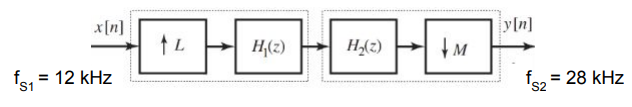

%- EL SISTEMA: x(n)->(L)->|h(n)|->(D)->y(n)
%señal de entrada
x = x_input.x;          X = fft(x, nfft);
%señal de entrada sobremuestreada.
x_l = upsample(x, L);   X_L= fft(x_l, nfft);
%señal de entrada sobremuestreada y filtrada
xh_l = conv(x_l,ls);    XH_L = fft(xh_l, nfft);
%señal de entrada sobremuestreada y filtrada y submuestreada
y= downsample(xh_l, M); Y = fft(y, nfft);

figure()
    hold on
    stem(0+retardo:length(x)-1+retardo, x)
    stem(0:Q:(length(y)-1)*Q, y)
    legend("x: entrada", "y: salida con Dow y Up-sample")
    grid on
    title("f_{s1}: 12 [Khz] a f_{s2}: 28 [Khz]")
    

#### Actividad 4 

#### Multietapa 

clc, clear; close all;
%ventana ideal: pasa bajos.
pb= @(nm, wc, N)( (wc/pi) .* sinc((wc/pi) .* (nm - N/2)) );
xx = sym('xx');

**Se desea decimar una señal con una tasa D=18, garantizando una banda de paso de wp= 0.02π. **

**a) Implemente un sistema como el de la Figura-a para decimar la señal en una sola etapa, considerando un filtro H(z) que garantice un ripple de δ= 3×10−3 mediante ventana de Kaiser. Calcule la salida del sistema completo y[n] para una entrada impulsiva. Grafique su respuesta en frecuencia para ω∈[0,π). ¿Cuál es el orden resultante para el filtro diseñado? **

D = 18;         %decimar.
wp = 0.02*pi;   %banda de paso.
%wp= wc - Dw/2; --> Dw = (wp - wc)*2
wc = pi/D;

Dw = abs( (wc - wp)*2 );
ripple = 3e-3;

%-% Ventana de Kaiser

%Obtengo los parametros de Kaiser.
A= -20*log10(ripple)

A = 50.4576

M = ceil( (A-8)/(2.285*Dw) + 1)

M = 85

N= M-1;
nm= 0:N;

%Funcion para calcular Beta
fBeta = piecewise(xx > 50,       0.1102*(xx-8.7), ...
        (21<= xx) & (xx <= 50),   0.5842*(xx-21)^0.4 + 0.07886*(xx-21), ...
                xx < 21,         0)

$$fBeta = \left\{ \begin{array}{cl} \frac{551\,\mathrm{xx}}{5000}-\frac{47937}{50000} & \text{ if }50<\mathrm{xx}\\ \frac{3943\,\mathrm{xx}}{50000}+\frac{2921\,{\left(\mathrm{xx}-21\right)}^{2/5}}{5000}-\frac{82803}{50000} & \text{ if }\mathrm{xx}\in \left[21,50\right]\\ 0 & \text{ if }\mathrm{xx}<21 \end{array}\right.$$

%Beta.
Beta = double(subs(fBeta, xx, A))

Beta = 4.6017


%filtro deseado. 
hd = pb(nm, wc, N);

%Numero de muestras para frecuencia.
nfft = 8192;

%Ventana de Kaiser.
w = linspace(0, 2*pi, nfft);
wk = kaiser(N+1, Beta)';
%Ventaneo con Kaiser.
h = hd.*wk;          %<---tambien es la respuesta impulsiva. hd x delta(n) = hd
OrdenKaiser= length(h)

OrdenKaiser = 85

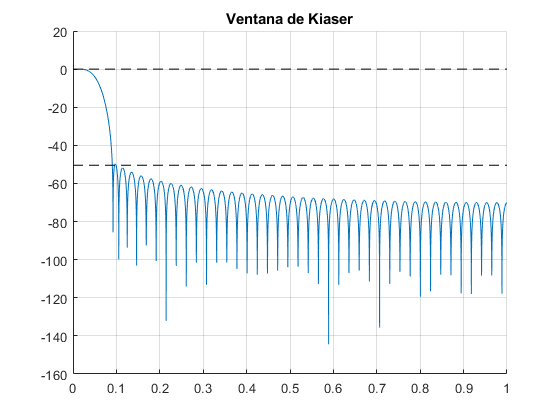

%-Veamos si cumple lo pedido:

figure()
    hold on;
    plot(w/pi, 20*log10( abs( fft(h, nfft) ) ))
    plot([0 1], [20*log10(1 + ripple), 20*log10(1 + ripple)], '--k')
    plot([0 1], [20*log10(1 - ripple), 20*log10(1 - ripple)], '--k')
    plot([0 1], [20*log10(ripple), 20*log10(ripple)], '--k')
    title("Ventana de Kiaser")
    xlim([0 1])
    grid on

    
%Cumple!!!!!!!
%Este filtro tiene una precuencia de corte muy chica por ende tendrá un
%orden muy grande, por ello se usa la decimacion para mejorar el orden.

**b) Ahora se requiere implementar el mismo sistema pero con un diseño equivalente en tres etapas, tal como se indica en la Figura-b. Suponiendo los factores de decimación D1= 3, D2= 3 y D3= 2 tal que D=D1D2D3, diseñe adecuadamente los filtros H1(z), H2(z) y H3(z) para obtener la misma respuesta que en punto a) (ayuda: ver Apéndice). Suponiendo una entrada impulsiva, grafique en frecuencia la salida de cada etapa de diezmado. ¿Con la asignación de frecuencias elegidas para cada filtro, se produce aliasing luego de cada decimación? ¿Se preserva la banda de frecuencia de interés definida para w≤wp?¿Qué órdenes resultaron para cada uno de estos tres filtros? Analice la ventajas de esta implementación respecto del sistema implementado en una sola etapa. **

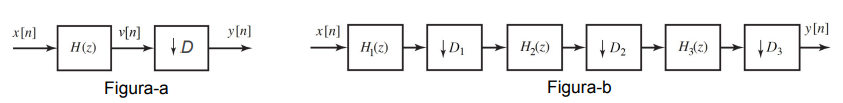

%D = 18;         %decimar.
%wp = 0.02*pi;   %banda de paso.
w0 = 2*pi; 

D1 =3; D2 = 3; D3 = 2;
D = D1*D2*D3;

wp1 = wp;
ws1 = ( 2/D1 - 1/(D1*D2*D3) )*pi; 
[M1, Beta1] = parametrosKaiser(ripple, abs(ws1 - wp1))

M1 = 12

Beta1 = 4.6017

WindK_1 = kaiser(M1, Beta1)';

%Donde va wc? es el ws en este caso o seguimos usando la definicion para la
%ventana deseada?

wp2 = D1*wp1;
ws2 = ( 2/D2 - 1/(D2*D3) )*pi; 
[M2, Beta2] = parametrosKaiser(ripple, abs(ws2 - wp2))

M2 = 15

Beta2 = 4.6017

WindK_2 = kaiser(M2, Beta2)';

wp3 = D2*wp2;
ws3 = ( 2/D3 - 1/(D3) )*pi; 
[M3, Beta3] = parametrosKaiser(ripple, abs(ws3 - wp3))

M3 = 20

Beta3 = 4.6017

WindK_3 = kaiser(M3, Beta3)';

OrdenDecimacion_tot = M1 + M2 + M3

OrdenDecimacion_tot = 47

function [M, Beta] = parametrosKaiser(ripple, Dw)
    %-% Ventana de Kaiser
    xx = sym('x');

    %Obtengo los parametros de Kaiser.
    A= -20*log10(ripple);
    M = ceil( (A-8)/(2.285*Dw) + 1);
    %N= M-1;
    %nm= 0:N;
    
    %Funcion para calcular Beta
    fBeta = piecewise(xx > 50,       0.1102*(xx-8.7), ...
            (21<= xx) & (xx <= 50),   0.5842*(xx-21)^0.4 + 0.07886*(xx-21), ...
                    xx < 21,         0);
    %Beta.
    Beta = double(subs(fBeta, xx, A));

end